Explore the[ Medical Ventilator With Lung Model ](https://www.mathworks.com/help/simscape/ug/medical-ventilator-with-lung-model.html)example.

- Open the model

openExample('simscape/MedicalVentilatorWithLungModelExample')

If you would like to change the model parameters, select the 

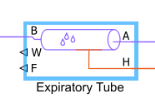

Double click on the expiratory tube to adjust block parameters:

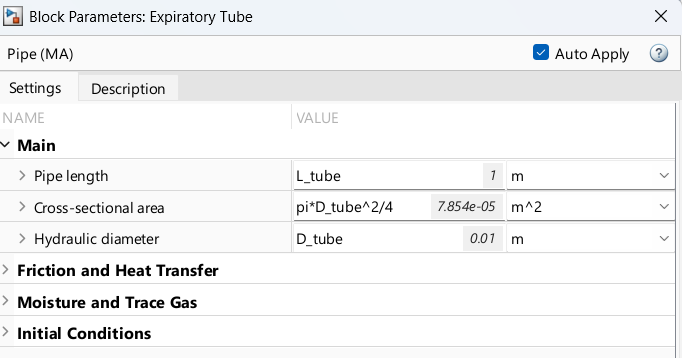

2. Run the model

3. Go to 'Plot Condensation in expiratory tube (see code)'.

See code will open, MedicalVentilatorWithLungModelPlot2Condensation.m

In lines 48 and 49, 

enter the following code:

Remove data points from the code and add Gaussian noise with the following code.

% Code to generate noisy ventilator data from 
load CondenseDat.mat t V

t = t(1:30:end); % Take every 100th point of t
V = V(1:30:end); % Take every 100th point of V
% Add noise to the V data
noiseLevel = .005; % Increase the noise level for more variation
V = V + noiseLevel * randn(size(V)); % Add Gaussian noise
% Plot the sampled data